clear all; close all; clc;

**Continuous distributions**

Normal distribution

1A

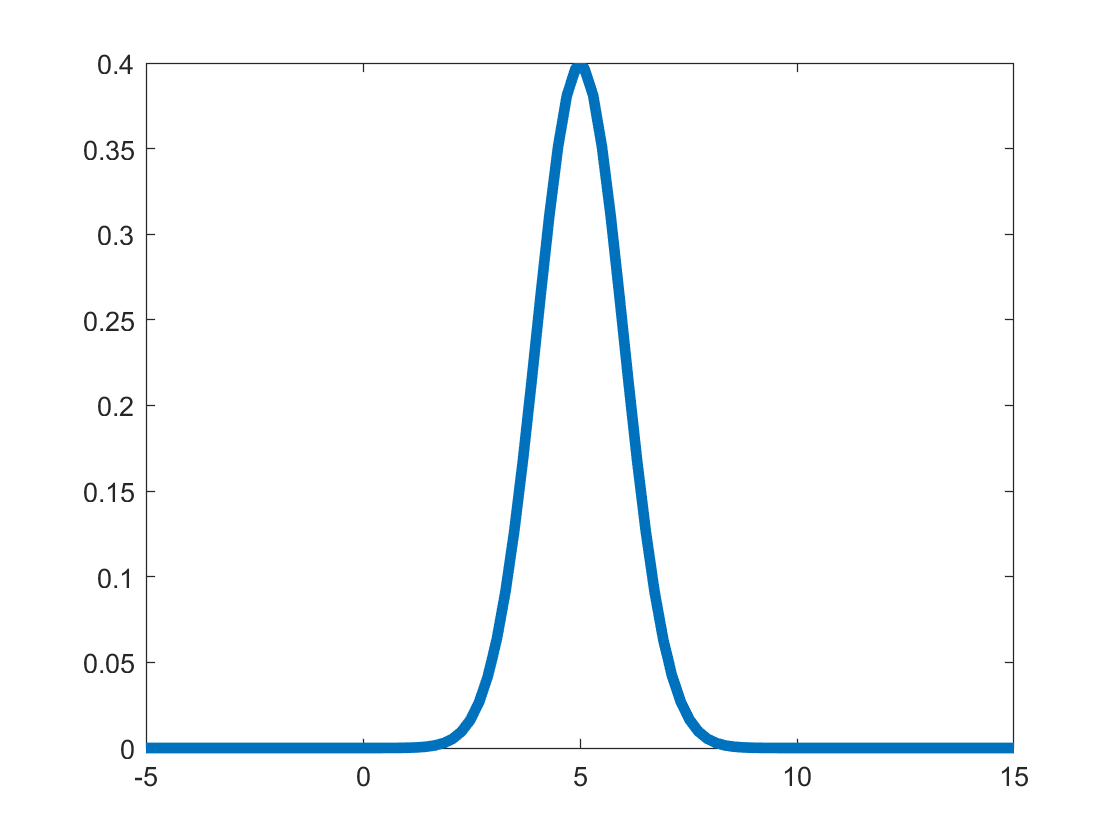


mu = 5;
sigma1 = 1;
sigma2 = 3;
x = linspace(-5,15,100); %
probdist1 = makedist('Normal',"mu",mu,"sigma",sigma1);
probdist2 = makedist('Normal',"mu",mu,"sigma",sigma2);
plot(x, pdf(probdist1,x), "LineWidth",4); %plot the normal dist with sigma = 1

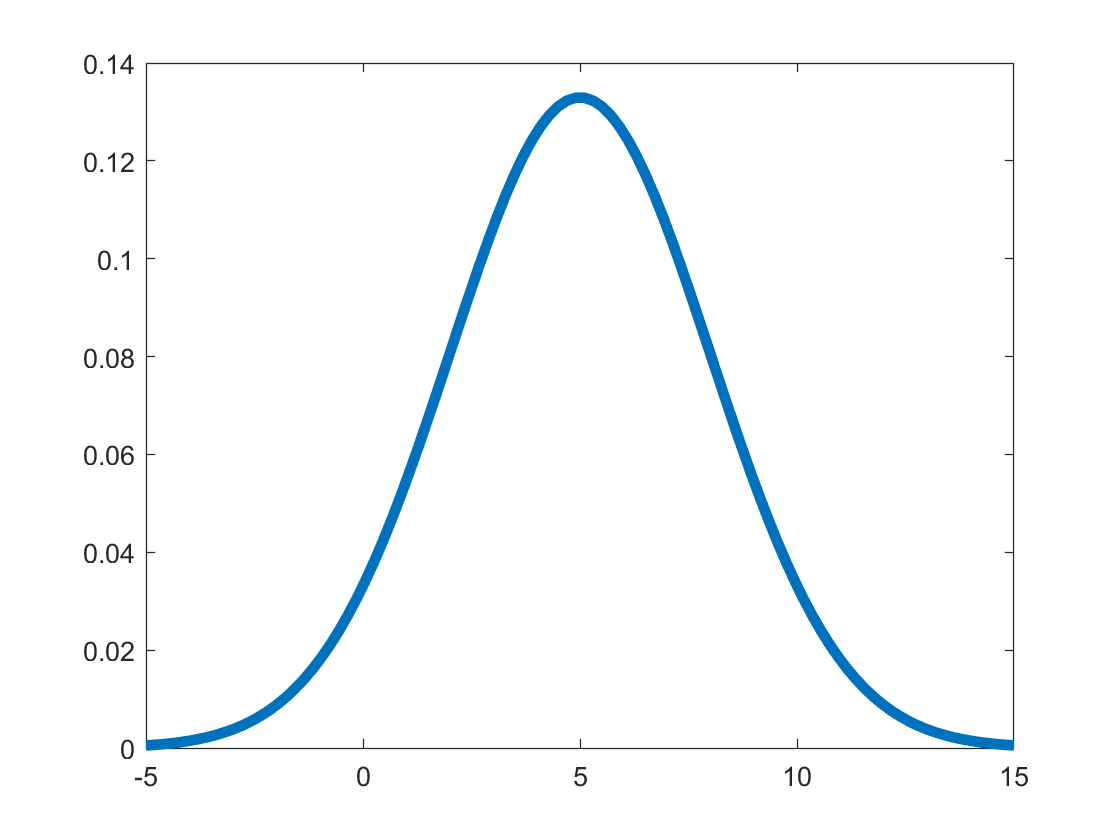

plot(x, pdf(probdist2,x), "LineWidth",4); %plot the normal dist with sigma = 3

1B

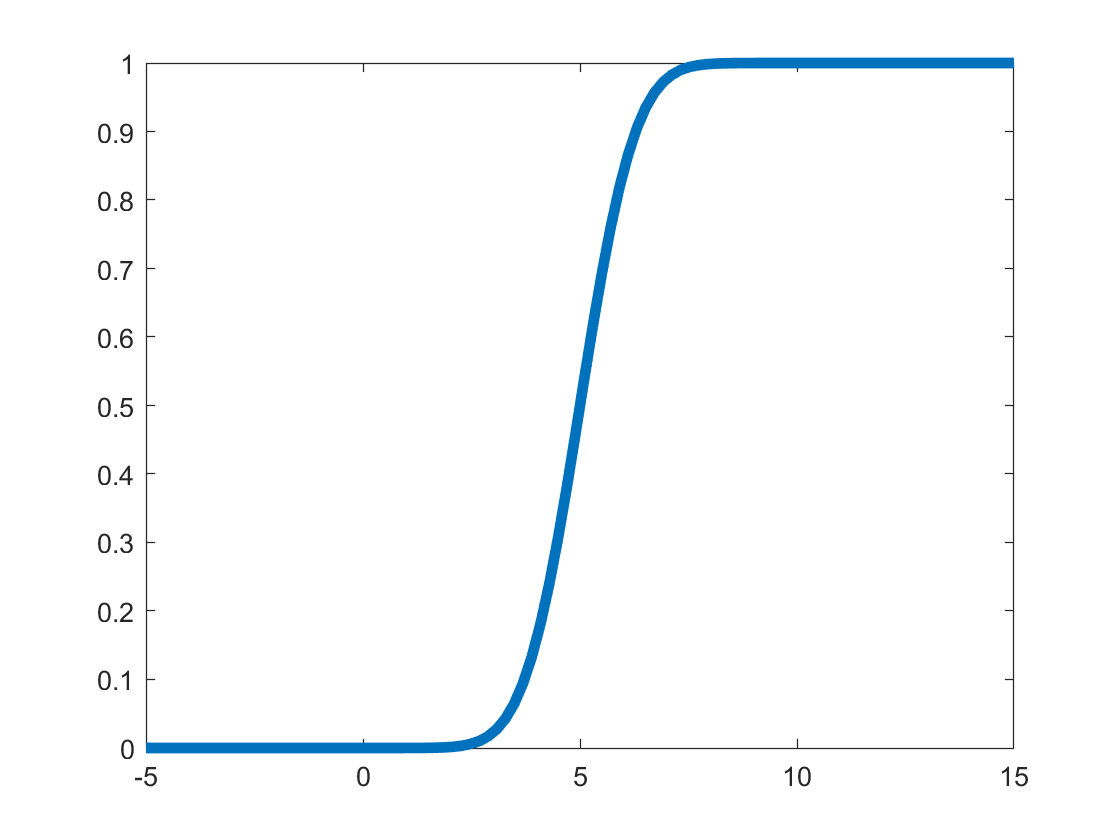

distfunc1 = normcdf(x,mu,sigma1);%plot the integral of normal dist with sigma = 1
plot(x,distfunc1,"LineWidth",4);

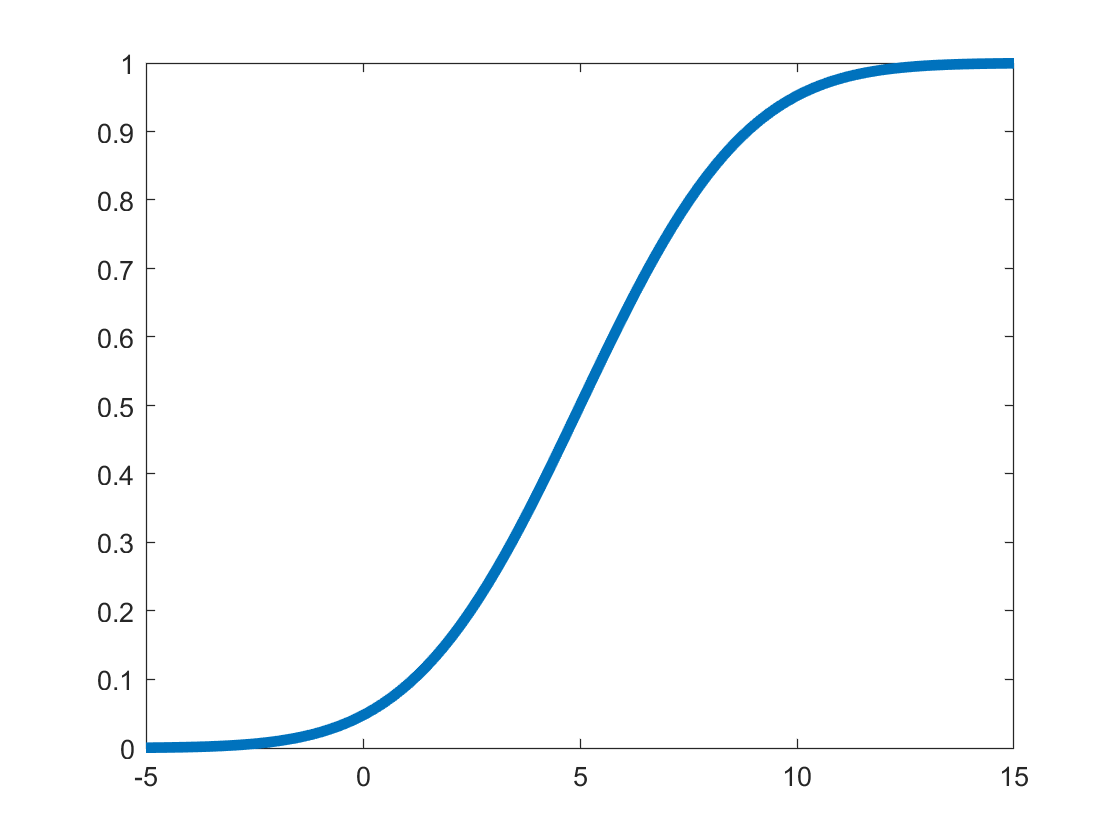

distfunc2 = normcdf(x,mu,sigma2);%plot the integral of normall dist with sigma = 3
plot(x,distfunc2,"LineWidth",4);

specificcdf = normcdf(0,mu,sigma2) %calculate the probability of value 0

specificcdf = 0.0478

1C

Sigma(0) should be = (0-5)/3 = -1.667

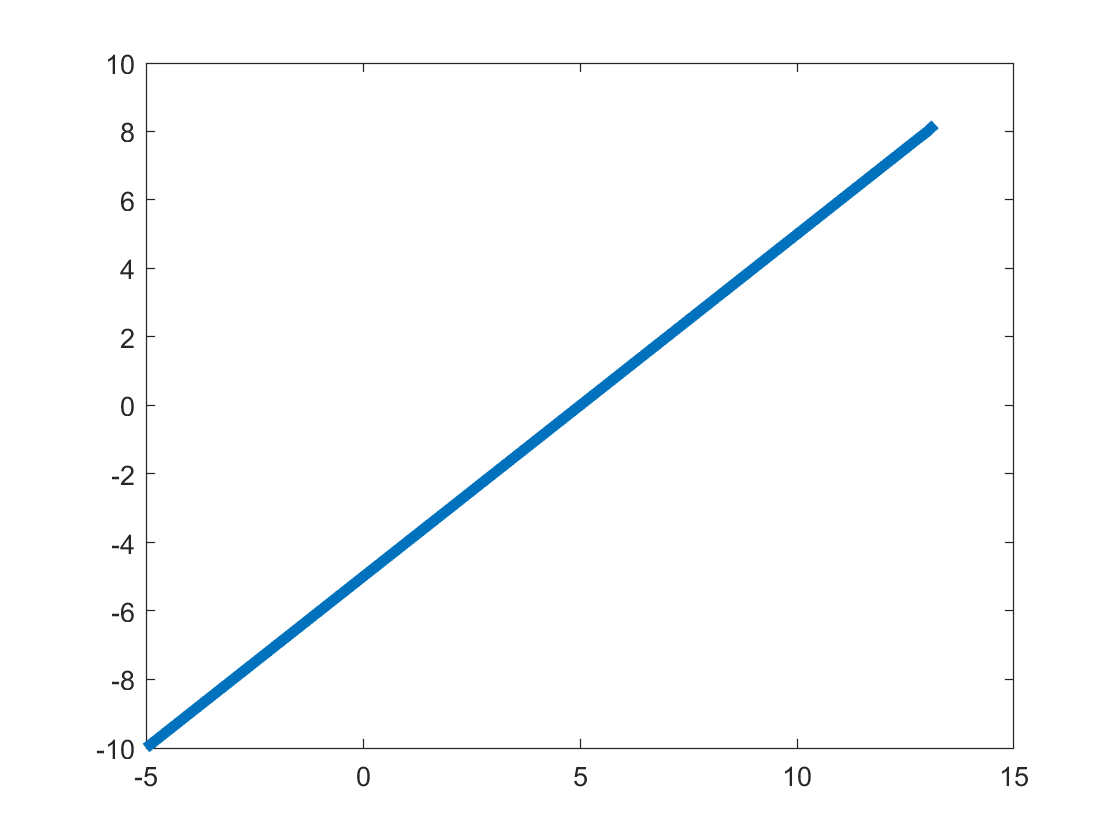

sigmavalues1 = norminv(distfunc1);%gives sigma value for each input
sigmavalues2 = norminv(distfunc2);
plot(x, sigmavalues1,"LineWidth",4);

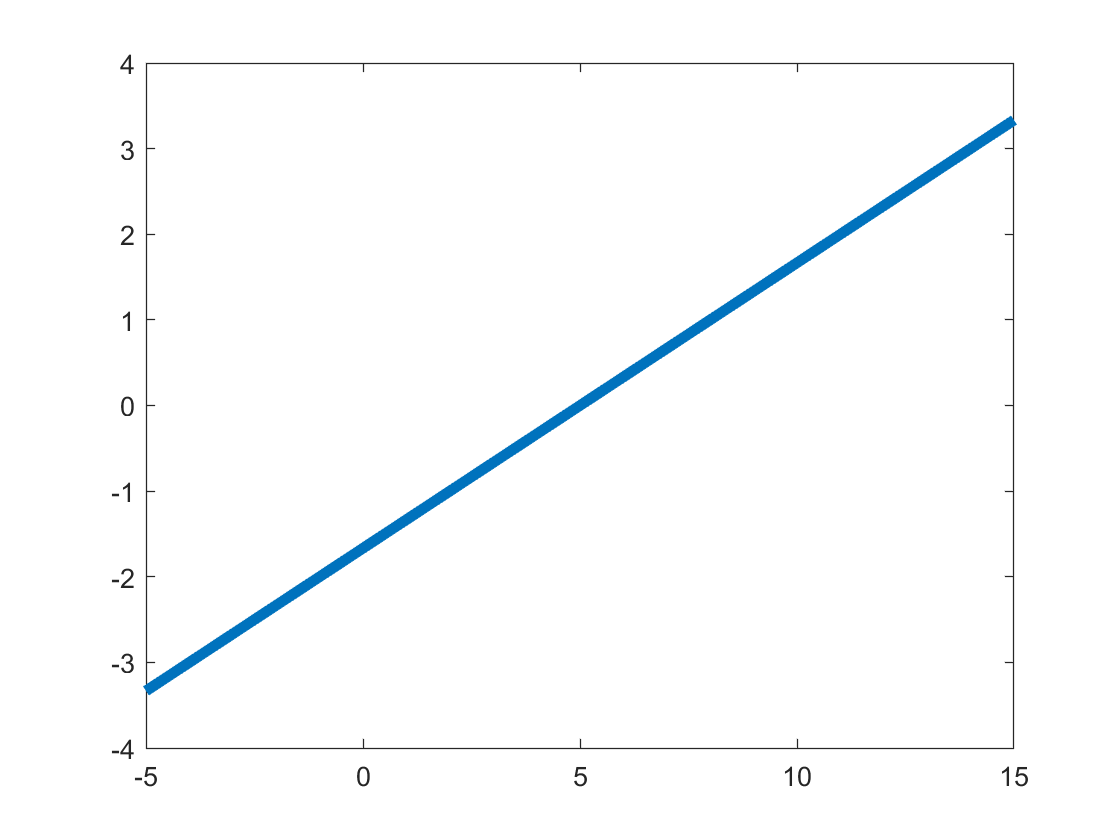

plot(x, sigmavalues2,"LineWidth",4);

specificsigma = norminv(specificcdf)

specificsigma = -1.6667

As we can see, the sigma distribution is linear, and the specific sigma that I calculated by hand is equivalent to the one from the norminv(cdf(pd(0)))

1D 

negative sigma values make sense because the left side of the graph values are smaller than the mean and sigma is defined as (x-mean)^2. When calculating specific sigma values, a negative sign appears for certain positive sigmas, we can look whether its samller or larger than mean to calculate the actual sign of sigma

2. I chose Rayleigh distribution 

2A The Rayleigh distribution is the distribution for a number of vectors with 2 degrees of freedom.  An example of the distribution arises in the case of random complex numbers whose real and imaginary components are independently and identically distributed Gaussian with equal variance and zero mean. In that case, the absolute value of the complex number is Rayleigh-distributed.

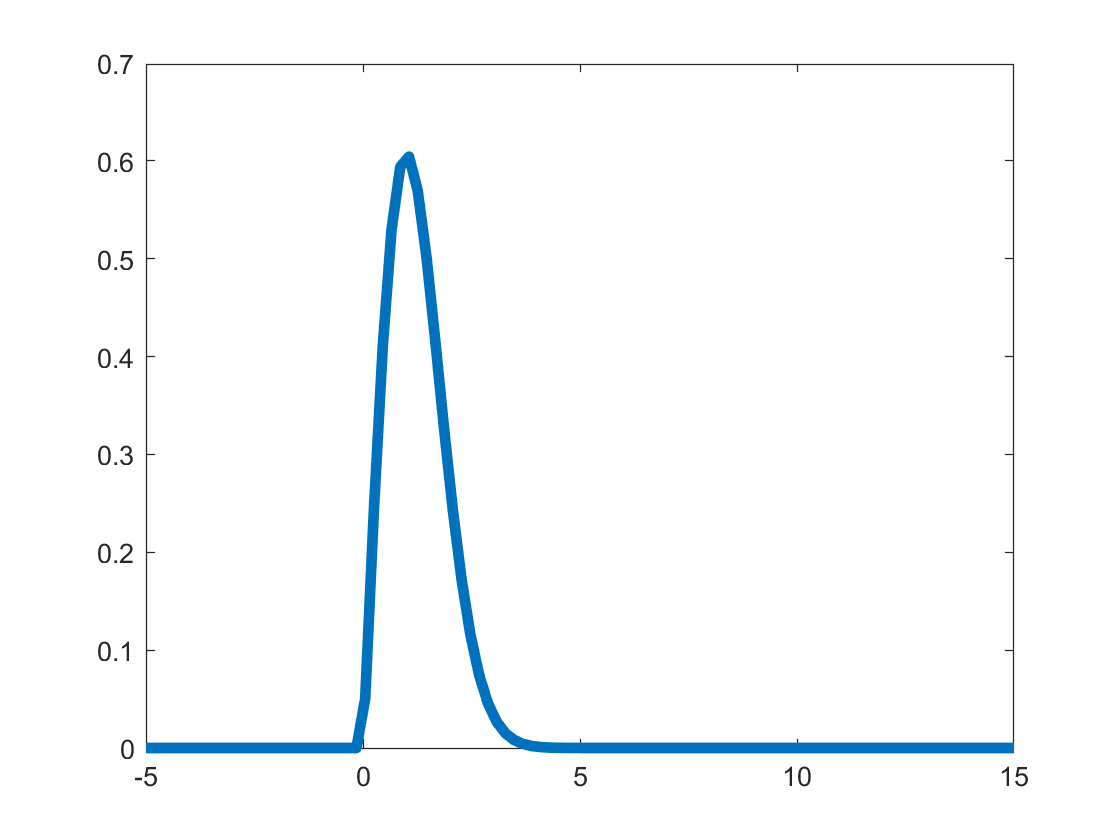

 y = linspace(0,10, 100000);
 b1 = 1; b2 = 3;
 rayl1 = makedist("Rayleigh",'b',b1);
 plot(x,pdf(rayl1,x),"LineWidth",4);

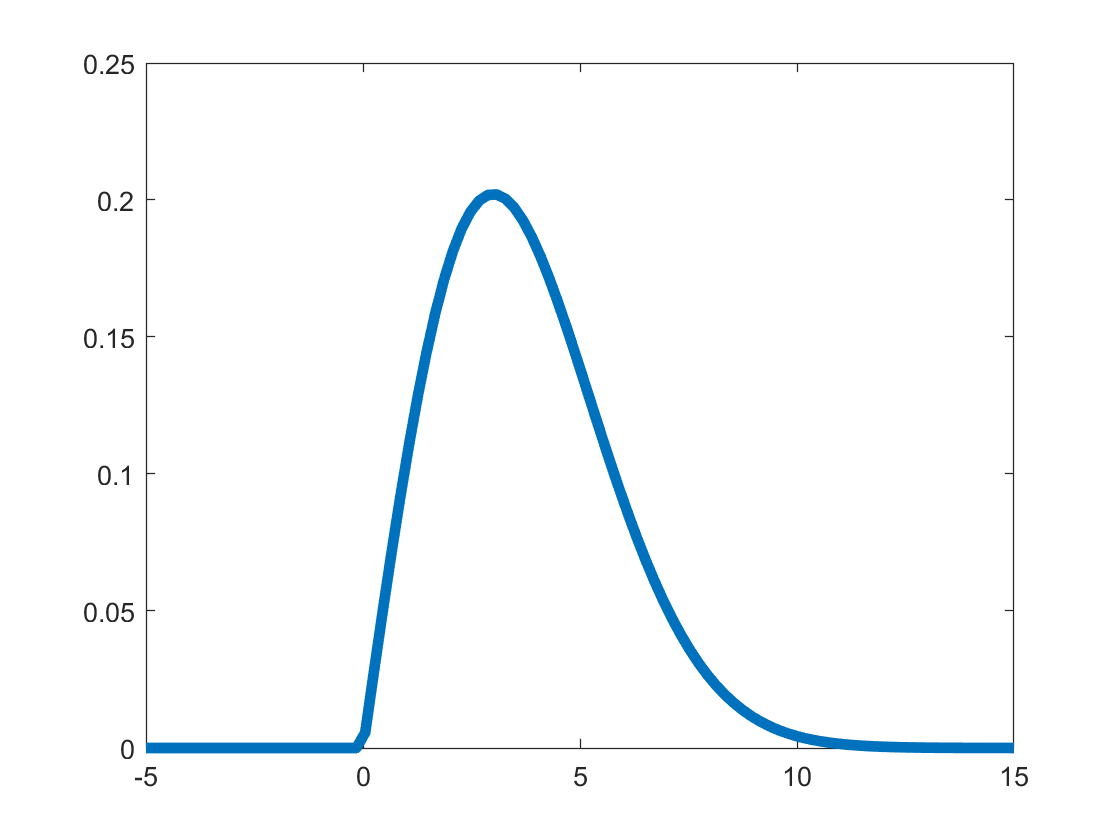

 rayl2 = makedist("Rayleigh",'b',b2);
 plot(x,pdf(rayl2,x),"LineWidth",4);

2B the b value is the scale parameter of the distribution. The larger b is, the more spread out the distribution is. Also, the value of b is the value of the median.

3. The hypothetical data I have is 100k complex vectors and their mean magnitude value is 3 (second Rayleigh distru=ibution graph)

3A My mean value for the measurement that I took is 7

3B If there is no signal, and my signal free data follows Rayleigh distribution, what is the probability that the data produces a distribution that is equally or more signal-like?

3C Probability = 2/sqrt(pi)*integral(0,7)e^(-x^2)dx

3D

 c = 7;
 probability7 = 1-cdf(rayl2,7)

probability7 = 0.0657

 probXsigma7=0.5*erfc(7/sqrt(2))

probXsigma7 = 1.2798e-12

Xsigma = 1.2798*10^-12 it's the probability that gaussian distributed signal-free data would give that measurement of 7. It is a very low probability.

3E sigma associated with value 7

 sigma3 = -norminv(probability7)

sigma3 = 1.5084

4. let's say we have four values: 1,7,10,15

Asking the question above: it's much more likely that the signal-free data produces value of 1 compared to 7,10,15

probability1 = 1-cdf(rayl2,1)

probability1 = 0.9460

probability10 = 1-cdf(rayl2,10)

probability10 = 0.0039

probability15 = 1-cdf(rayl2,15)

probability15 = 3.7267e-06

probXsigma1=0.5*erfc(1/sqrt(2))

probXsigma1 = 0.1587

probXsigma10=0.5*erfc(10/sqrt(2))

probXsigma10 = 7.6199e-24

probXsigma15=0.5*erfc(15/sqrt(2))

probXsigma15 = 3.6710e-51

sigma1 = -norminv(probability1)

sigma1 = -1.6069

sigma10 = -norminv(probability10)

sigma10 = 2.6636

sigma15 = -norminv(probability15)

sigma15 = 4.4803

**Non-continuous distribution**

 Binomial distribution

1A 

N = number of entries

p = location of peak on the distribution of N values (Range 0-1)

1B

I made a list of 40 values of x, and a corresponding pdf

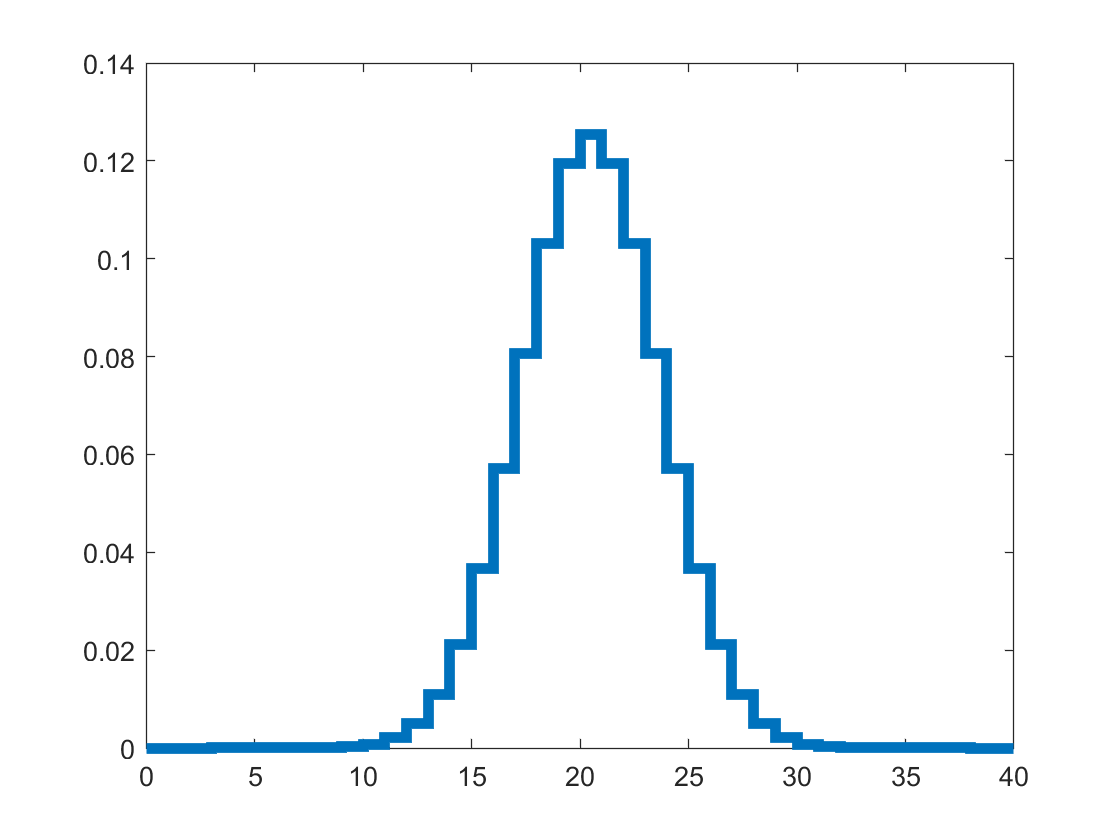

x = 0:40;
bin1 = makedist("Binomial",'N',40, 'p',0.5); 
stairs(x,pdf(bin1,x),"LineWidth",4);

N = 40 is equivalent to the number of values of x, so p = 0.5 is around 20

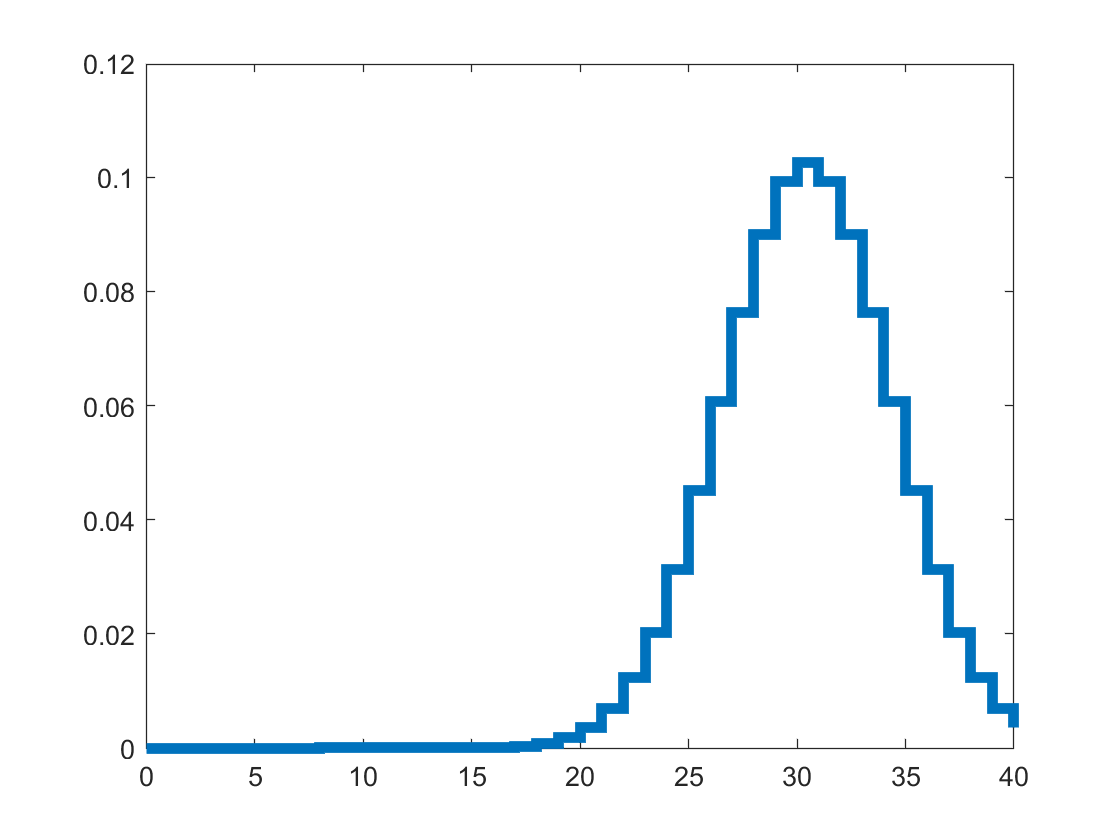

bin2 = makedist("Binomial",'N',60, 'p',0.5); 
stairs(x,pdf(bin2,x),"LineWidth",4);

N = 80 is bigger than the number of entries so the p value is around 0.5*60=30 which is where the peak is located

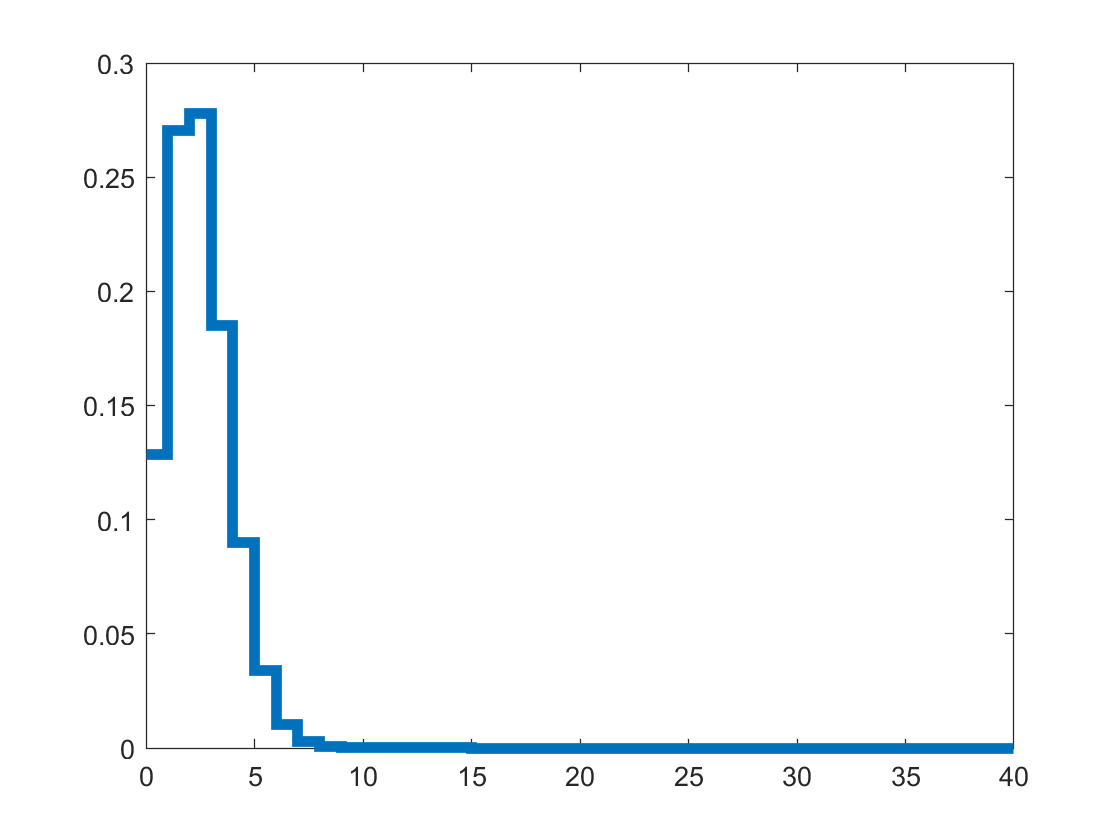

bin3 = makedist("Binomial",'N',40, 'p',0.05); 
stairs(x,pdf(bin3,x),"LineWidth",4);

Location of the peak is p*N = 0.05*40 = 2

1C

If there is no signal, and my signal-free data follows the distribution, what is the probability that data produces the distribution that is equally, or more, signal-like?

I have a collected value of 20 for the bin2 distribution:

probability20 = 1-cdf(bin2,20)

probability20 = 0.9933

probXsigma20=0.5*erfc(20/sqrt(2))

probXsigma20 = 2.7536e-89

sigma20 = -norminv(probability20)

sigma20 = -2.4706

That's an extremely low probability^. 

1D

Because the probabilities and sigmas are discrete, certain values aquired experimentally might not fit the accepted range of possible values which would mean that one needs a high number of input data

1E 

Because the mean is the average and not the median, it might be in between two data points. For example, average between [1,2,4,5] is 3 even though it is not present in the data set. Same goes for sigmas.